clear
clc
T = @(alpha) [cosd(alpha) sind(alpha) 0 0 0 0;
              sind(alpha) cosd(alpha) 0 0 0 0;
              0 0 1 0 0 0;
              0 0 0 cosd(alpha) sind(alpha) 0; 
              0 0 0 sind(alpha) cosd(alpha) 0;
              0 0 0 0 0 1];
L = 800;
L1 = L*sqrt(2);
EA = 7.2*10^6;
EJ = 2.3438 * 10^9;
q = -1; u_hat = 1; th_hat = deg2rad(1);

K1_not_rot = EA./L1.*[1 0 0 -1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0; -1 0 0 1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0]+...
            2*EJ./L1^3.*[0 0 0 0 0 0; 0 6 -3*L1 0 -6 -3*L1; 0 -3*L1 2*L1^2 0 3*L1 L1^2; 0 0 0 0 0 0; 0 -6 3*L1^2 0 6 3*L1; 0 -3*L1 2 0 3*L1  2*L1^2];
K1 = T(45)'*K1_not_rot*T(45)

K1 = 1.0e+06 *

    0.0032    0.0032   -0.0078   -0.0032   -0.0032   -0.0078
    0.0032    0.0032   -0.0078   -0.0032   -0.0032   -0.0078
   -0.0078   -0.0078    8.2866    0.0078    0.0078    4.1433
   -0.0032   -0.0032    8.7892    0.0032    0.0032    0.0078
   -0.0032   -0.0032    8.7892    0.0032    0.0032    0.0078
   -0.0078   -0.0078    0.0000    0.0078    0.0078    8.2866


K2 = EA./L.*[1 0 0 -1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0; -1 0 0 1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0]+...
            2*EJ./L^3.*[0 0 0 0 0 0; 0 6 -3*L 0 -6 -3*L; 0 -3*L 2*L^2 0 3*L L^2; 0 0 0 0 0 0; 0 -6 3*L^2 0 6 3*L; 0 -3*L 2 0 3*L  2*L^2]

K2 = 1.0e+07 *

    0.0009         0         0   -0.0009         0         0
         0    0.0000   -0.0022         0   -0.0000   -0.0022
         0   -0.0022    1.1719         0    0.0022    0.5859
   -0.0009         0         0    0.0009         0         0
         0   -0.0000    1.7578         0    0.0000    0.0022
         0   -0.0022    0.0000         0    0.0022    1.1719


K3_not_rot = EA./L.*[1 0 0 -1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0; -1 0 0 1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0]+...
            2*EJ./L^3.*[0 0 0 0 0 0; 0 6 -3*L 0 -6 -3*L; 0 -3*L 2*L^2 0 3*L L^2; 0 0 0 0 0 0; 0 -6 3*L^2 0 6 3*L; 0 -3*L 2 0 3*L  2*L^2]

K3_not_rot = 1.0e+07 *

    0.0009         0         0   -0.0009         0         0
         0    0.0000   -0.0022         0   -0.0000   -0.0022
         0   -0.0022    1.1719         0    0.0022    0.5859
   -0.0009         0         0    0.0009         0         0
         0   -0.0000    1.7578         0    0.0000    0.0022
         0   -0.0022    0.0000         0    0.0022    1.1719


K3 = T(270)'*K3_not_rot*T(270)

K3 = 1.0e+07 *

    0.0000         0    0.0022   -0.0000         0    0.0022
         0    0.0009         0         0   -0.0009         0
    0.0022         0    1.1719   -0.0022         0    0.5859
   -0.0000         0   -1.7578    0.0000         0   -0.0022
         0   -0.0009         0         0    0.0009         0
    0.0022         0    0.0000   -0.0022         0    1.1719




k_EJ3 = 2*EJ/L1^3 * [6, -3*L1, -6, -3*L1;
                -3*L1, 2*L1^2, 3*L1, L1^2;
                -6, 3*L1, 6, 3*L1;
                -3*L1, L1^2, 3*L1, 2*L1^2]; % local frame
K_EA3 = zeros(6); K_EA3([2, 5], [2, 5]) = EA/L1 * [1, -1;-1, 1];

K_EJ3 = zeros(6); K_EJ3([1, 3, 4, 6], [1, 3, 5, 6]) = k_EJ3;
K3a = zeros(6); K3a(4:6, 4:6) = K_EA3(1:3, 1:3) + K_EJ3(1:3,1:3);


K = zeros(6,6);
K(1:3,1:3) = K(1:3,1:3) + K1(4:6,4:6);
K = K + K2;
%K(4:6,4:6) = K(4:6,4:6) + K3(1:3,1:3)
K = K + K3a

K = 1.0e+07 *

    0.0012    0.0003    0.0008   -0.0009         0         0
    0.0003    0.0003   -0.0014         0   -0.0000   -0.0022
    0.0008   -0.0014    2.0006         0    0.0022    0.5859
   -0.0009         0         0    0.0009         0   -0.0011
         0   -0.0000    1.7578         0    0.0006    0.0022
         0   -0.0022    0.0000   -0.0011    0.0022    2.0006


syms x;
N = [1 - 3*(x/L)^2+2*(x/L)^3; L*(-(x/L)+2*(x/L)^2-(x/L)^3); 3*(x/L)^2-2*(x/L)^3; L*((x/L)^2-(x/L)^3)];
f = int(N.*q,x,0,L)

$$f = \left(\begin{array}{c} -400\\ \frac{160000}{3}\\ -400\\ -\frac{160000}{3} \end{array}\right)$$

F = [0 f(1) f(2) 0 f(3) f(4)];
K_new = K([1 2 3 5],[1 2 3 5]);
F = [0 f(1) f(2) f(3)]'-u_hat.*K([1 2 3 5],4)-th_hat.*K([1 2 3 5],6);
K_new

K_new = 1.0e+07 *

    0.0012    0.0003    0.0008         0
    0.0003    0.0003   -0.0014   -0.0000
    0.0008   -0.0014    2.0006    0.0022
         0   -0.0000    1.7578    0.0006


u = double(K_new \ F)

u =     1.0207
   -1.0832
    0.0017
   -4.8602


K3(6,:)*[u_hat u(4) th_hat 0 0 0]'

ans = 2.1973e+04

%% Ex 1
clear
clc

L1 = 800;
EA = 7.2e6;
EJ = 2.3438e9;
q = 1;
us = 1;
ts = -deg2rad(1); % rotazione inversa rispetto convenzione
L2 = L1*sqrt(2);

k_EJ2 = 2*EJ/L1^3 * [6, -3*L1, -6, -3*L1;
                -3*L1, 2*L1^2, 3*L1, L1^2;
                -6, 3*L1, 6, 3*L1;
                -3*L1, L1^2, 3*L1, 2*L1^2]; % local frame
k_EJ3 = 2*EJ/L1^3 * [6, -3*L1, -6, -3*L1;
                -3*L1, 2*L1^2, 3*L1, L1^2;
                -6, 3*L1, 6, 3*L1;
                -3*L1, L1^2, 3*L1, 2*L1^2]; % local frame

k_EJ1 = 2*EJ/L2^3 * [6 -3*L2, -6, -3*L2;
                -3*L2, 2*L2^2, 3*L2, L2^2;
                -6, 3*L2, 6, 3*L2;
                -3*L2, L2^2, 3*L2, 2*L2^2];

T_truss = @(a) [cos(a), sin(a), 0, 0; 0, 0 , cos(a), sin(a)];
T_beam = @(a) [cos(a), sin(a), 0, 0, 0, 0; sin(a), cos(a), 0, 0, 0, 0; 0, 0, 1, 0, 0, 0; 0, 0, 0, cos(a), sin(a), 0; 0, 0, 0, sin(a), cos(a), 0; 0, 0, 0, 0, 0, 1];

k_EA1 = T_truss(pi/4)'*EA/(L2)*[1, -1; -1, 1]*T_truss(pi/4); % local beam 1
K_EJ1 = zeros(6); K_EJ1([2, 3, 5, 6], [2, 3, 5, 6]) = k_EJ1;
K_EJ1 = T_beam(pi/4)'*K_EJ1;


K_EA2 = zeros(6); K_EA2([1, 4], [1, 4]) = EA/L1 * [1, -1;-1, 1];
K_EA3 = zeros(6); K_EA3([2, 5], [2, 5]) = EA/L1 * [1, -1;-1, 1];
K_EJ2 = zeros(6); K_EJ2([2, 3, 5, 6], [2, 3, 5, 6]) = k_EJ2;
K_EJ3 = zeros(6); K_EJ3([1, 3, 4, 6], [1, 3, 5, 6]) = k_EJ3;
K_EA1 = zeros(6); K_EA1([1, 2, 4, 5], [1, 2, 4, 5]) = k_EA1;

F = [0, -q*L1/2, q*L1^2/12, 0, -q*L1/2, -q*L1^2/12]';

K1a = zeros(6); K1a(1:3, 1:3) = K_EA1(4:6, 4:6) + K_EJ1(4:6,4:6);
K2a = zeros(6); K2a = K_EA2 + K_EJ2;
K3a = zeros(6); K3a(4:6, 4:6) = K_EA3(1:3, 1:3) + K_EJ3(1:3,1:3);

Ka = K1a + K2a + K3a

Ka = 1.0e+07 *

    0.0012    0.0003    0.0008   -0.0009         0         0
    0.0003    0.0003   -0.0014         0   -0.0000   -0.0022
         0   -0.0011    2.0006         0    0.0022    0.5859
   -0.0009         0         0    0.0009         0   -0.0022
         0   -0.0000    0.0022         0    0.0009    0.0022
         0   -0.0022    0.5859   -0.0022    0.0022    2.3438



F2 = -Ka(:, [4, 6])*[us, ts]'  % forze calcolate

F2 = 1.0e+05 *

    0.0900
   -0.0038
    1.0227
   -0.0944
    0.0038
    4.3104



Ka = Ka([1, 2, 3, 5], [1, 2, 3, 5]);
Fa = F + F2; Fa = Fa([1, 2, 3, 5]);


U = Ka\Fa

U =     1.0622
   -1.2501
    0.0071
   -0.0267


## ex 2

clear; clc; close all;
L = 1000; EJ1 = 2*10^10; EJ2 = 10^10; k = 20; P = 100;
syms x;
phi = (x/(2*L))^2;
dphi = diff(phi); ddphi = diff(dphi);
K = int(ddphi^2*EJ1,x,0,L)+int(ddphi^2*EJ2,x,L,2*L)+subs(phi^2,x,L)*k;
F = subs(phi,x,L)*P;  
c = double(F/K)

c = 2.8571

double(c*subs(phi,x,L))

ans = 0.7143

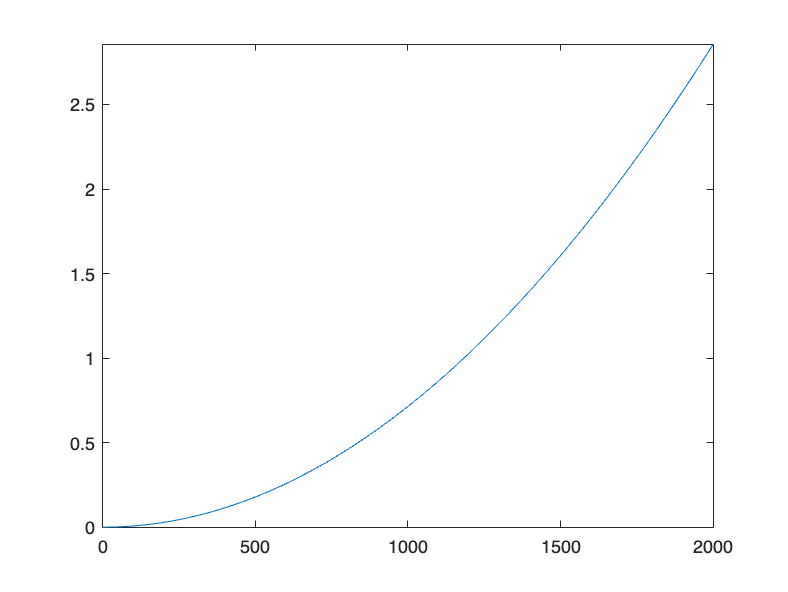

fplot(c*phi,[0 2*L])
hold off;


clear; clc; close all;
L = 1000; EJ1 = 2*10^10; EJ2 = 10^10; k = 20; P = 100;
syms x;
phi = [(x/L)^2 1+2*x/L];
dphi = diff(phi); ddphi = diff(dphi);
K = int(ddphi(1)^2*EJ1,x,0,L)+int(ddphi(2)^2*EJ2,x,0,L)+subs(phi(1)^2,x,L)*k;
F = subs(phi(1),x,L)*P;
c = double(F/K)

c = 1

figure
double(c*subs(phi(2),x,L))

ans = 3

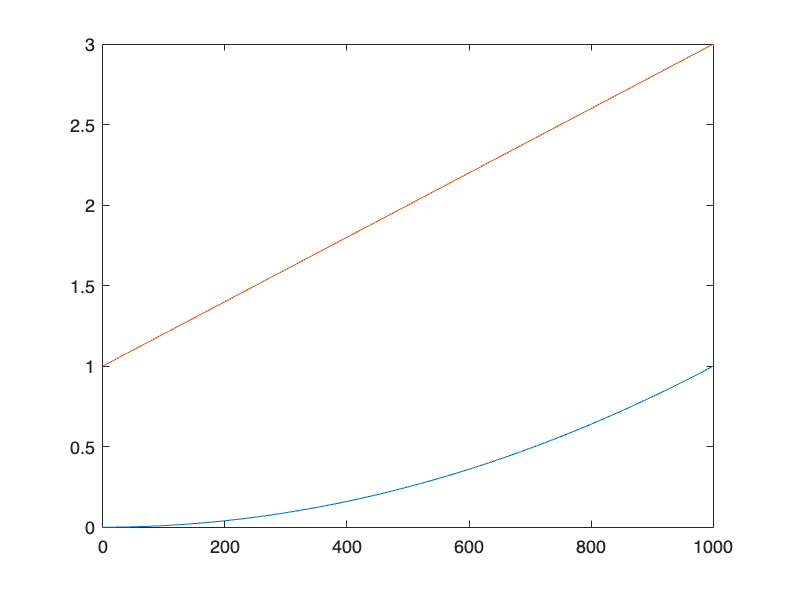

fplot(c*phi(1),[0 L]); hold on; fplot(c*phi(2),[0 L]); hold off;